## 1. Image Loading

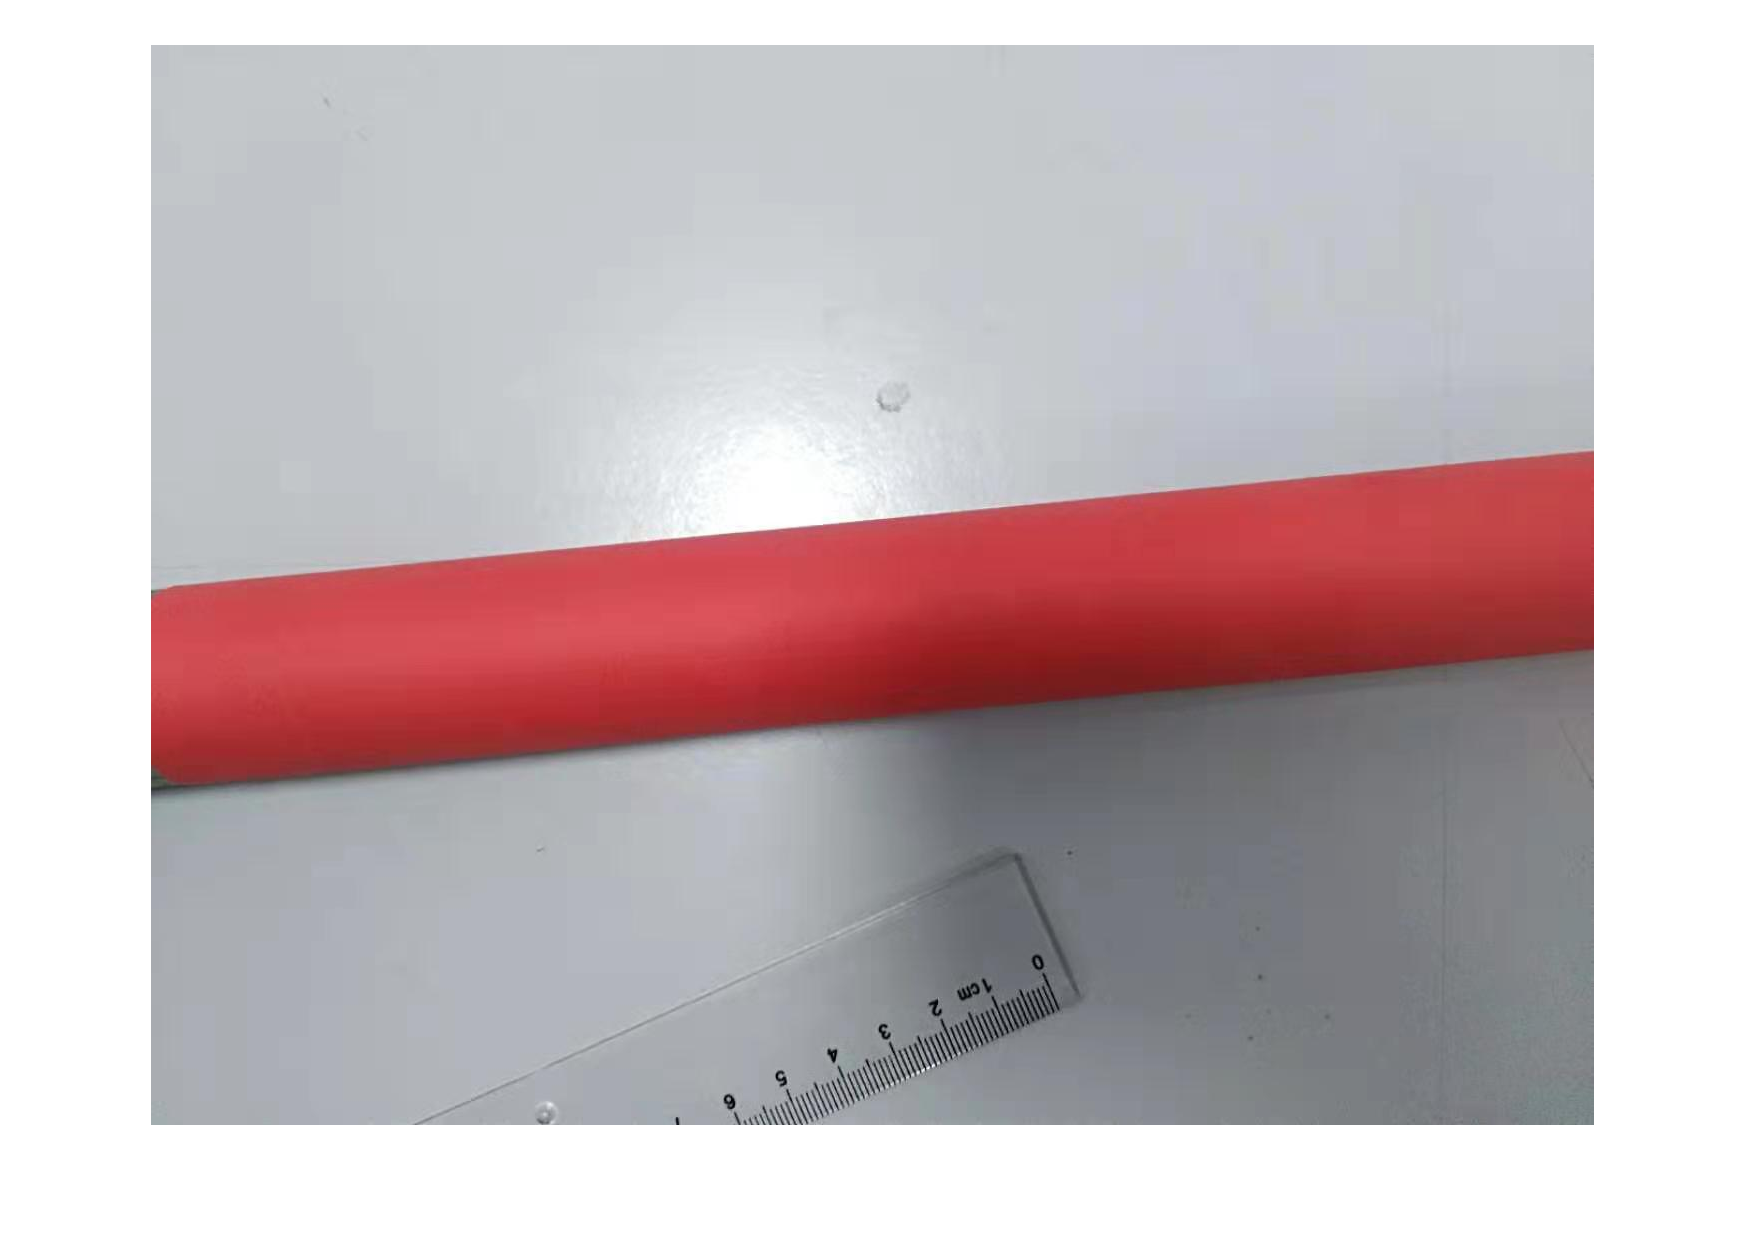

img = imread("./data/3.jpg");
img = im2double(img);
width=size(img,2);
height=size(img,1);
length = sqrt(width*height);

figure, imshow(img);

## 2. Hough Transform

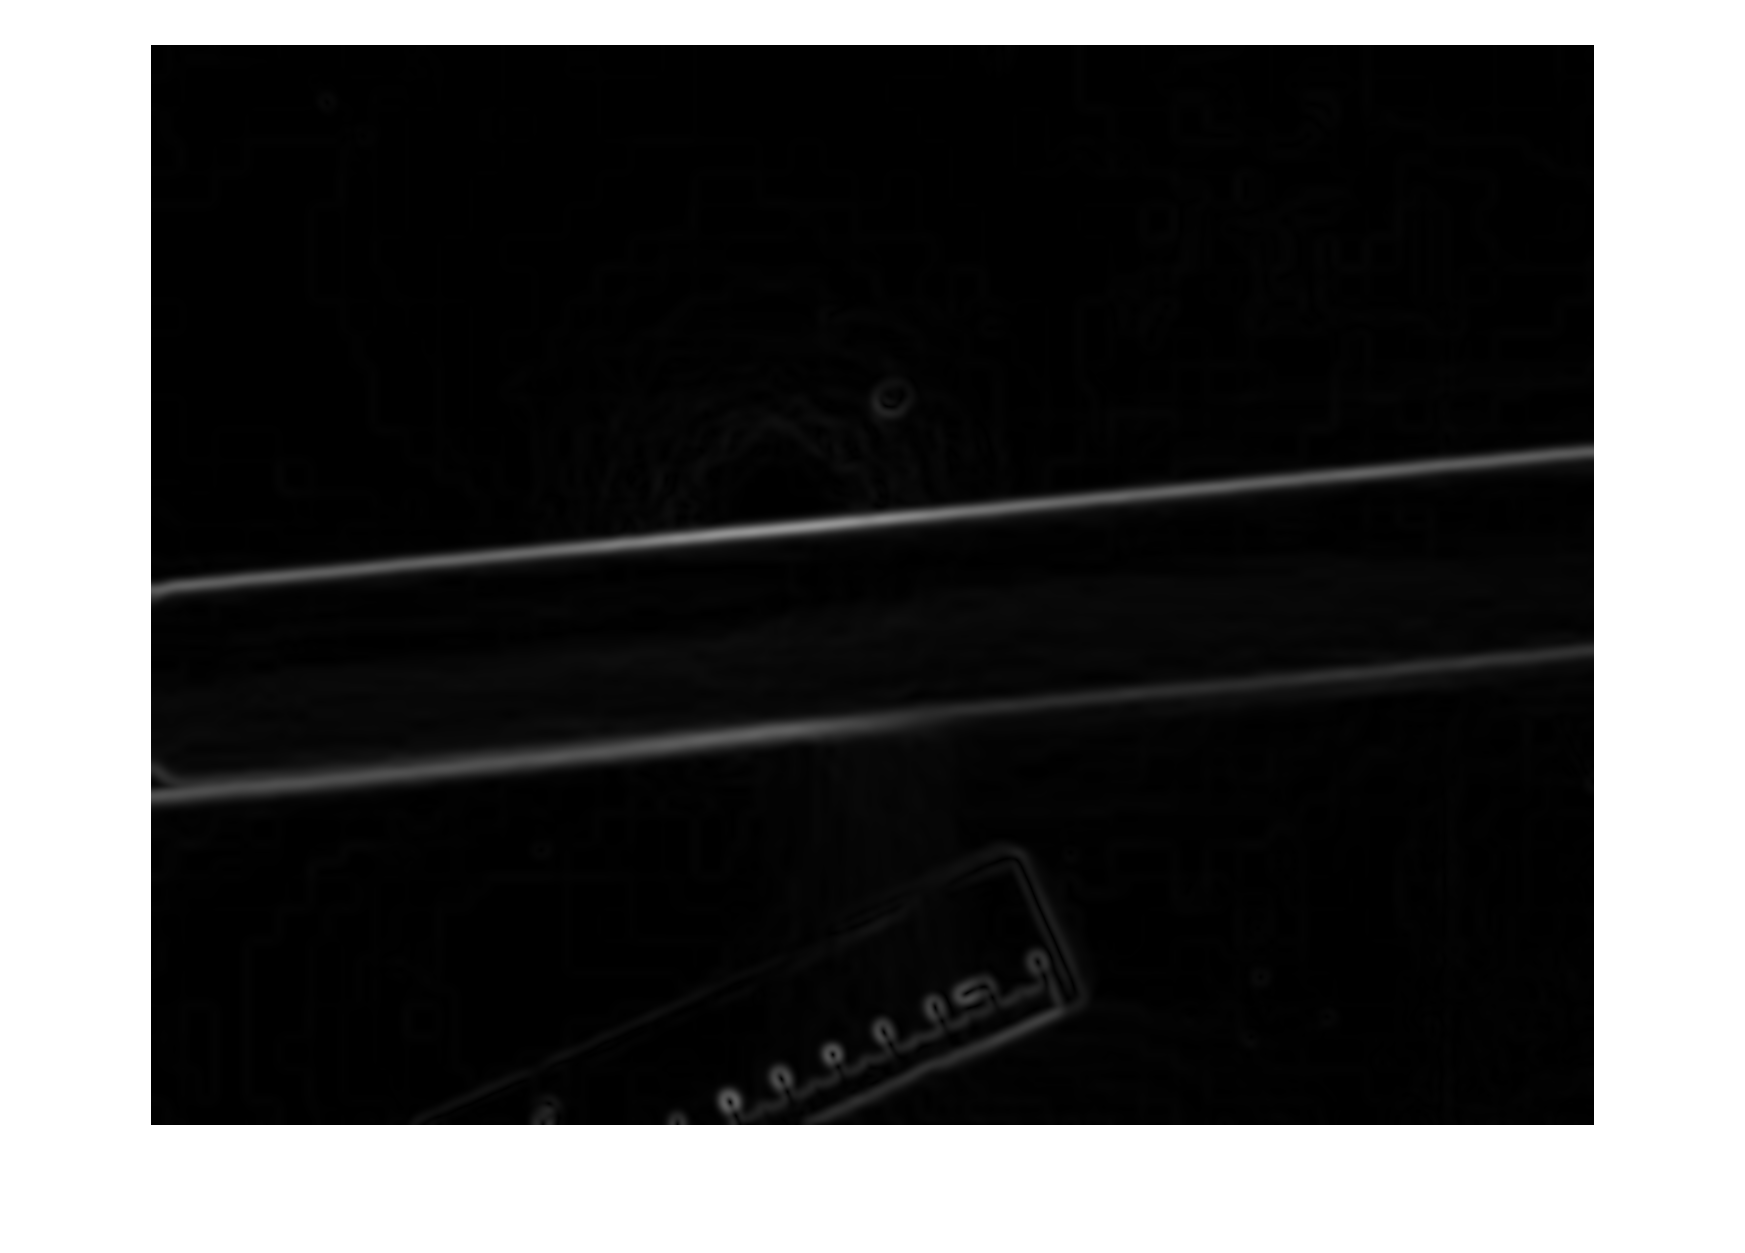

edges = compute_edges(img,5);

figure, imshow(edges);

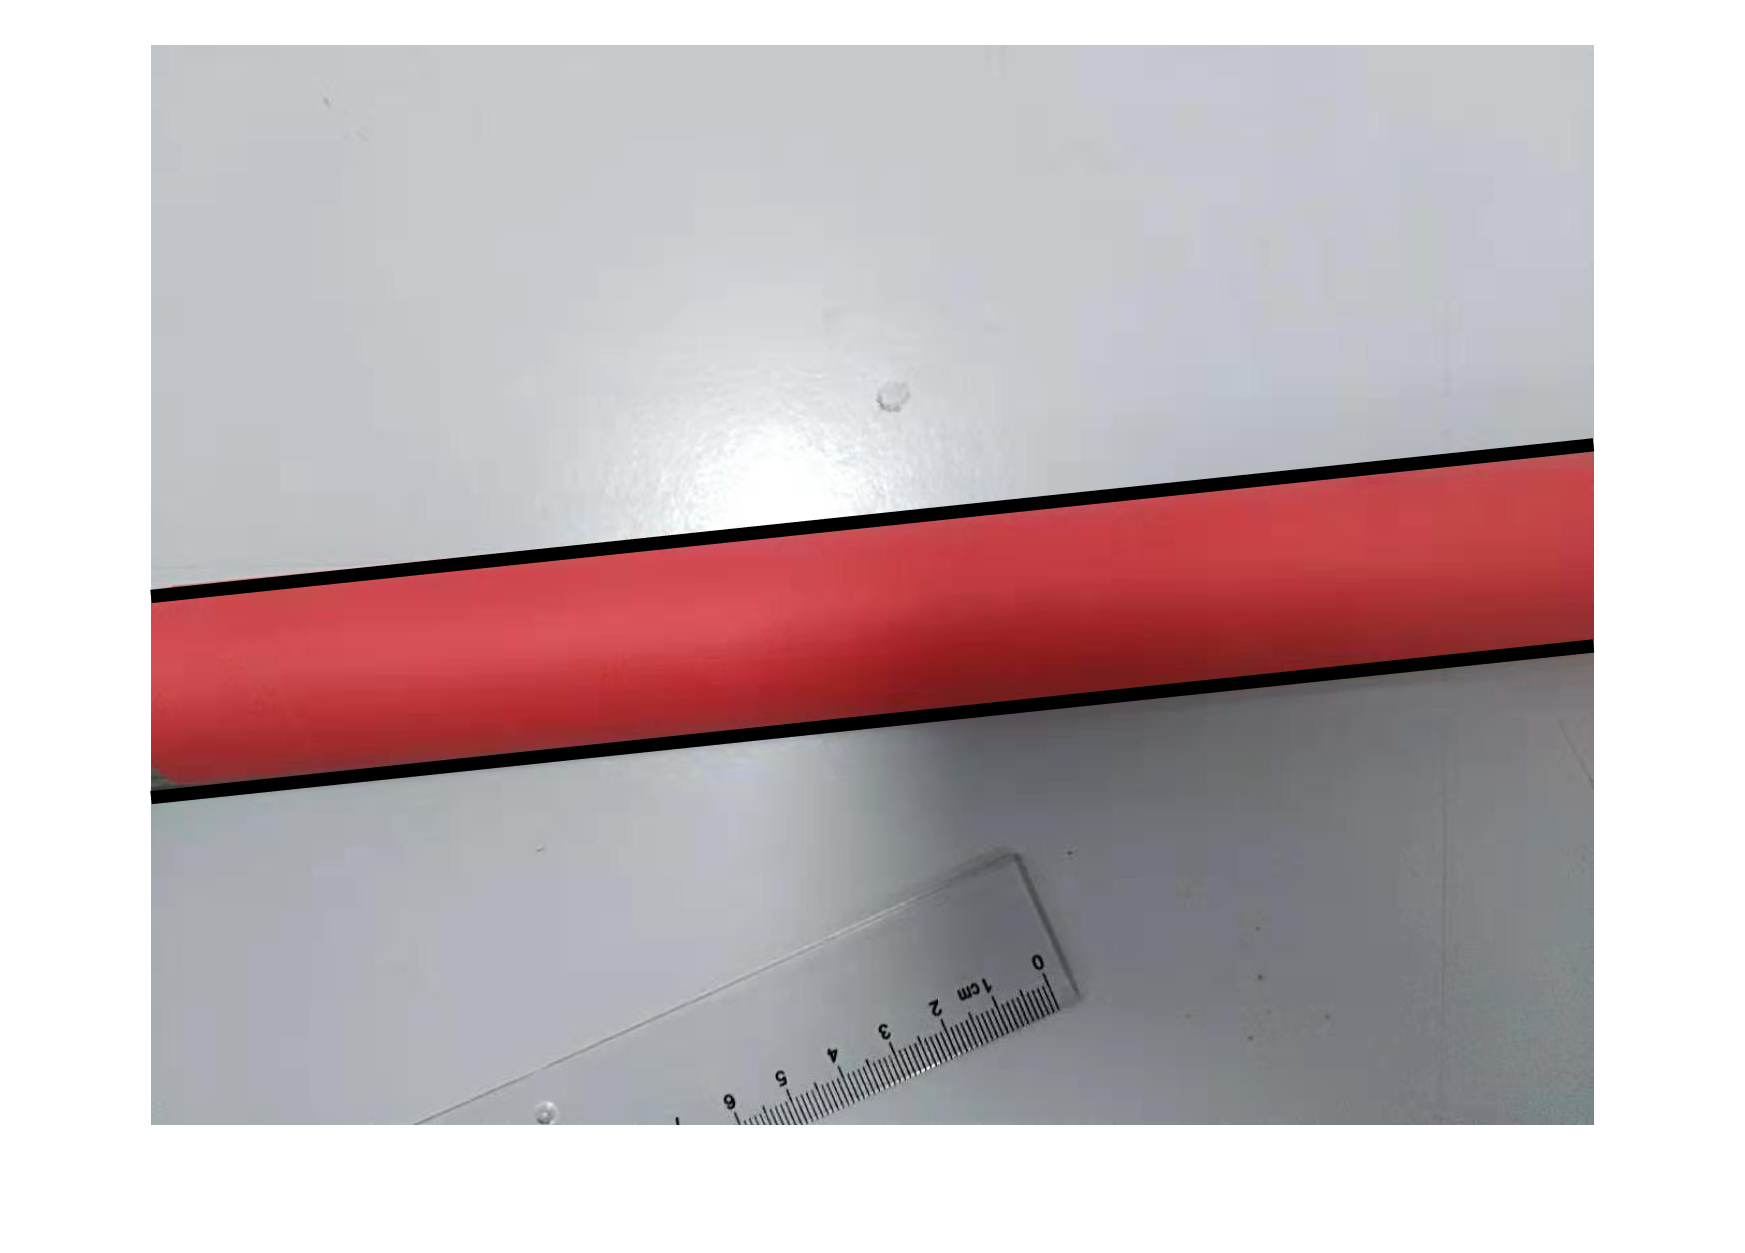

[theta1, rho1, theta2, rho2] = find_parallel(edges,0.03);

figure; imshow(img), hold on
plot_line(width,height,theta1,rho1);
plot_line(width,height,theta2,rho2);

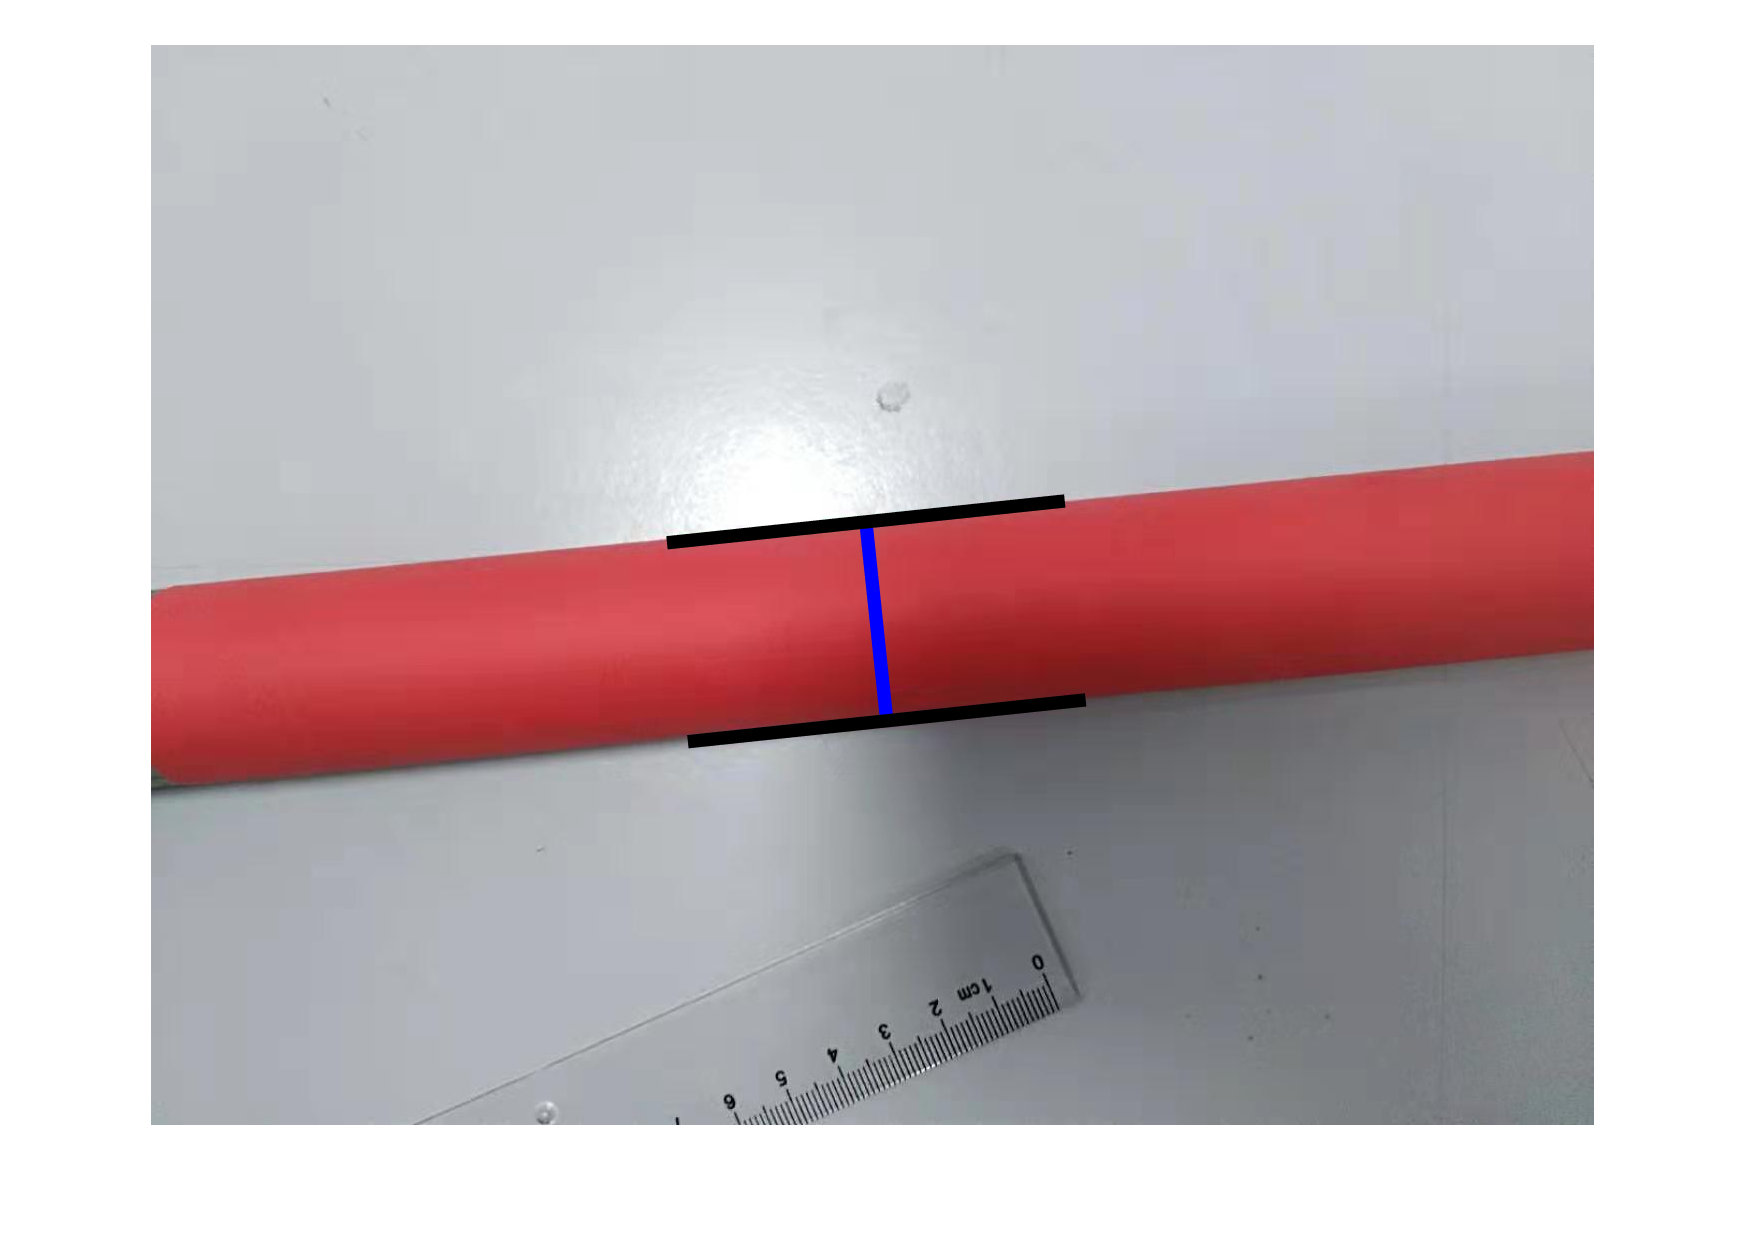

[p1, p2] = initial_points(theta1,rho1,theta2,rho2,width,height);

figure, imshow(img), hold on
plot_ruler(p1,p2);

p1 = p1 + randn(size(p1))*(length/100);
p2 = p2 + randn(size(p2))*(length/100);

## 3. Gradient Decent

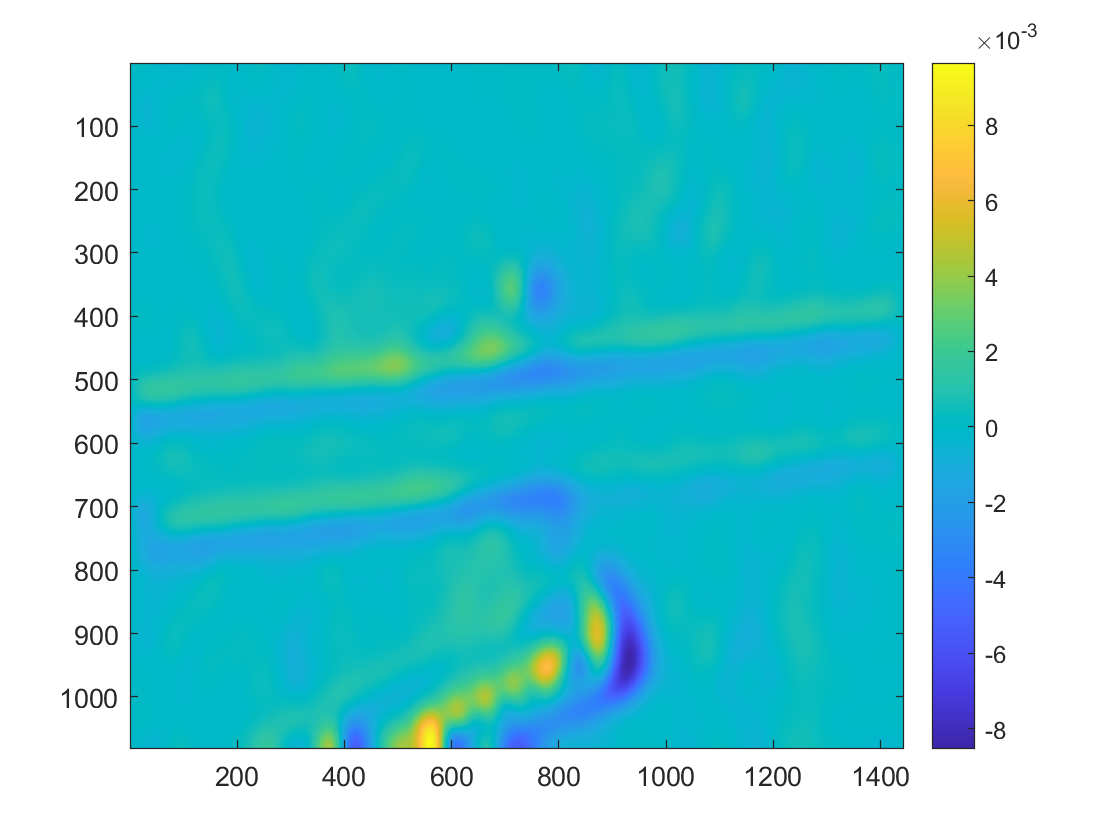

grad = compute_grad(edges,25);

figure, imagesc(grad(:,:,1)), colorbar;

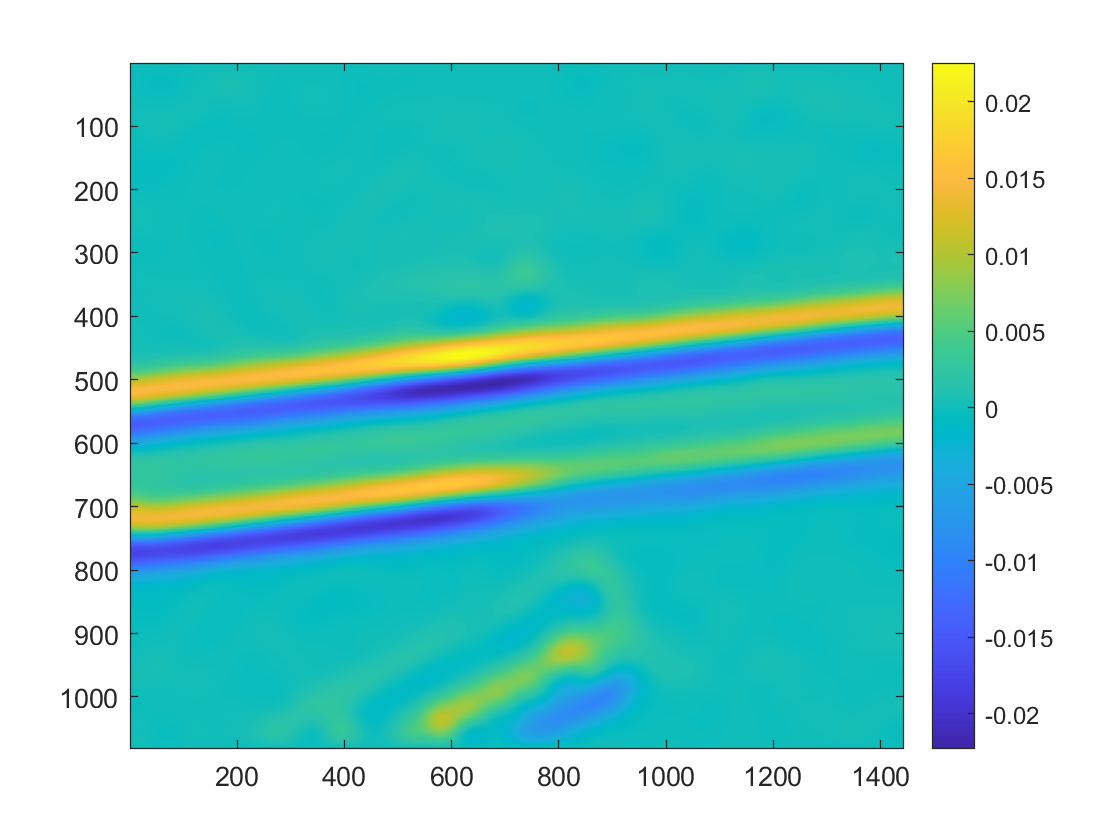

figure, imagesc(grad(:,:,2)), colorbar;

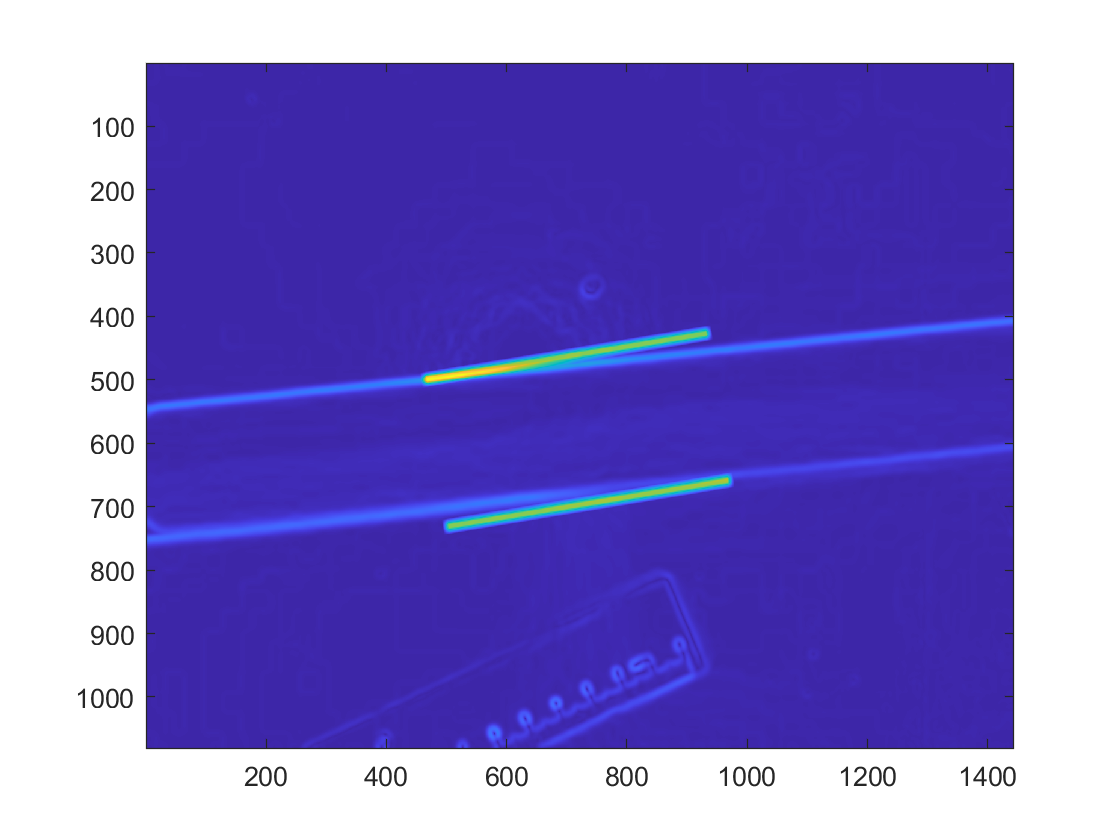

[pxs, pys] = meshgrid(1:width,1:height);
ps = zeros(0,0,0);
ps(:,:,1) = pxs;
ps(:,:,2) = pys;

[line1, line2] = lines_mask(p1,p2,ps,5,10);

figure, imagesc(line1+line2+edges), hold on

decent_rate = 1.0

decent_rate = 1

momentum = 1

momentum = 1

damping = 0.3

damping = 0.3000


thickness = 5

thickness = 5

expand = 1

expand = 1


pan_m = 0.0002*length*(thickness+expand)

pan_m = 1.4980

rot_m = 0.005*length*length*(thickness+expand)

rot_m = 4.6753e+04

spr_m = 0.1*length

spr_m = 124.8375

v1=0;
v2=0;

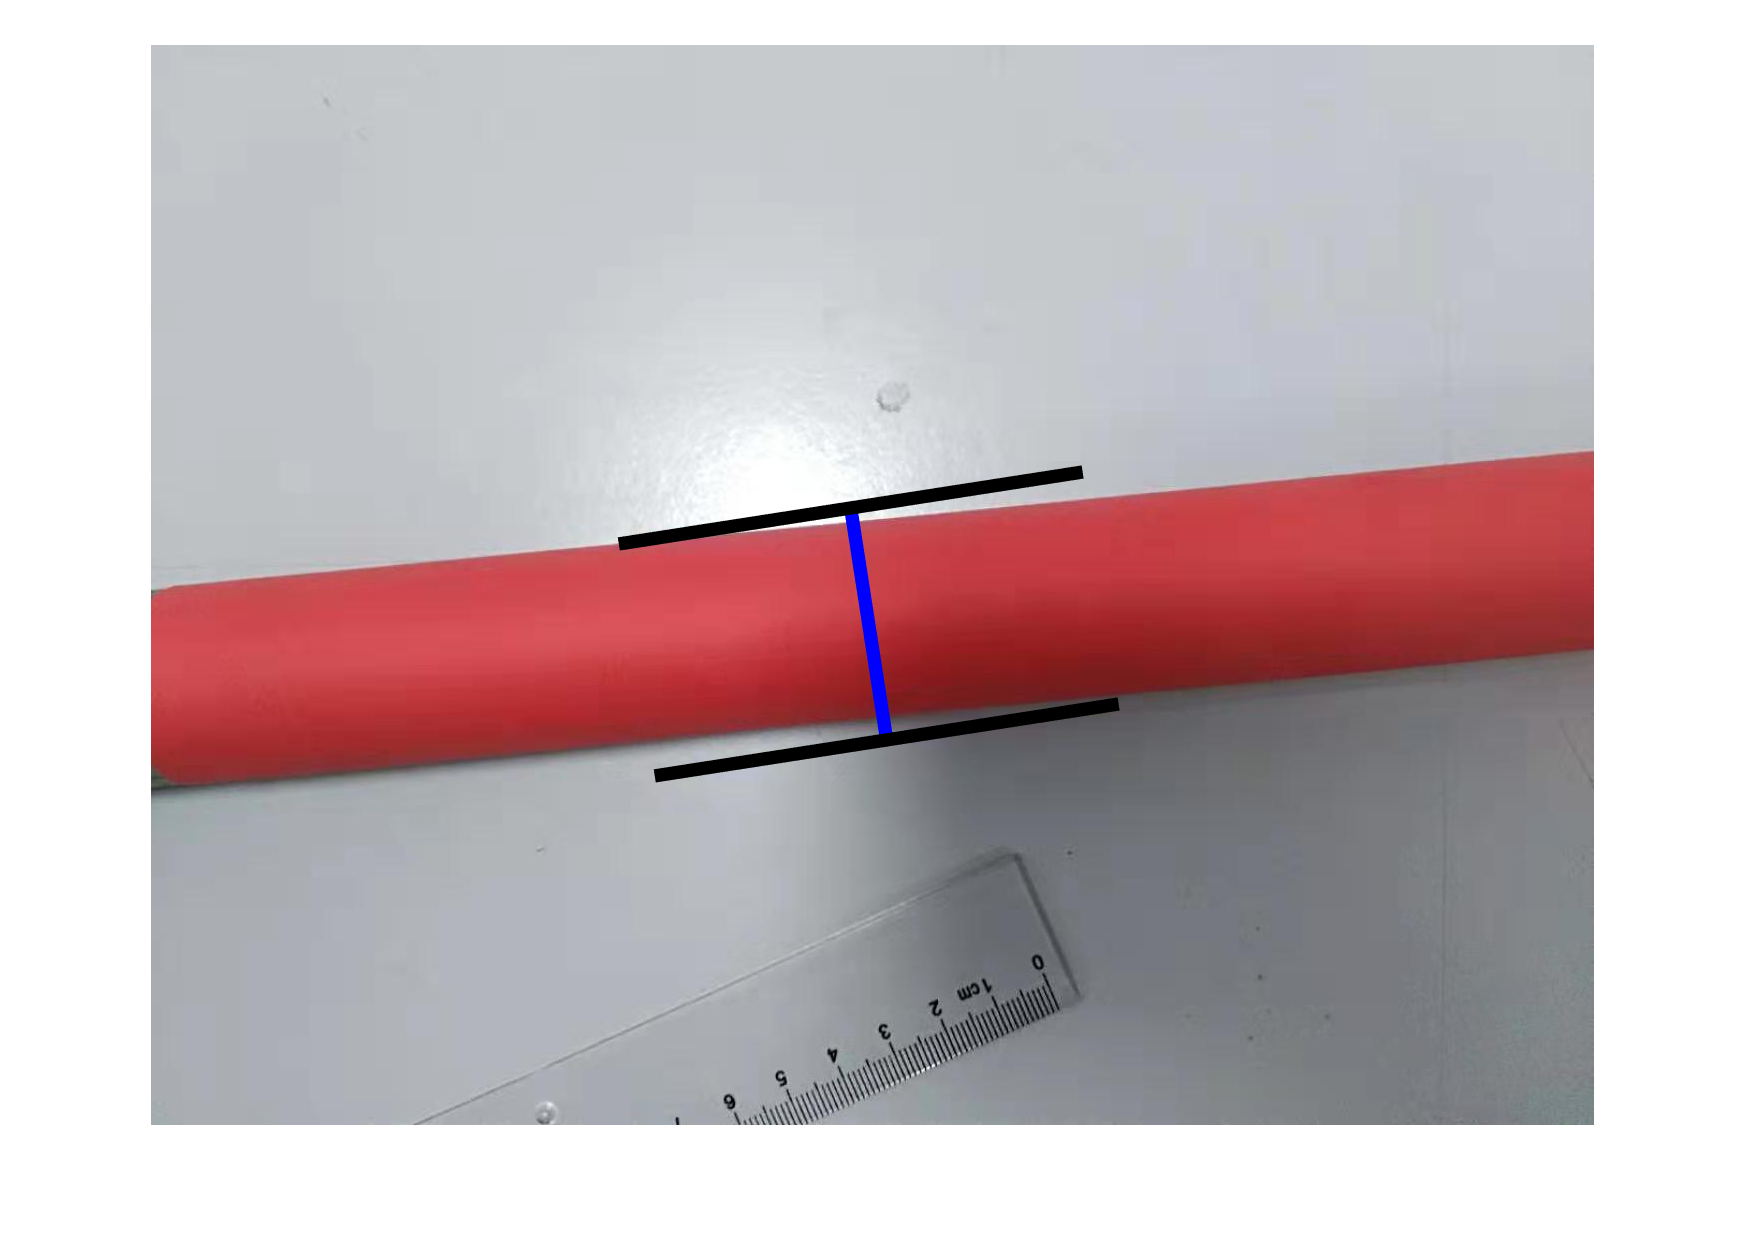

figure, imshow(img), hold on
plot_ruler(p1,p2);

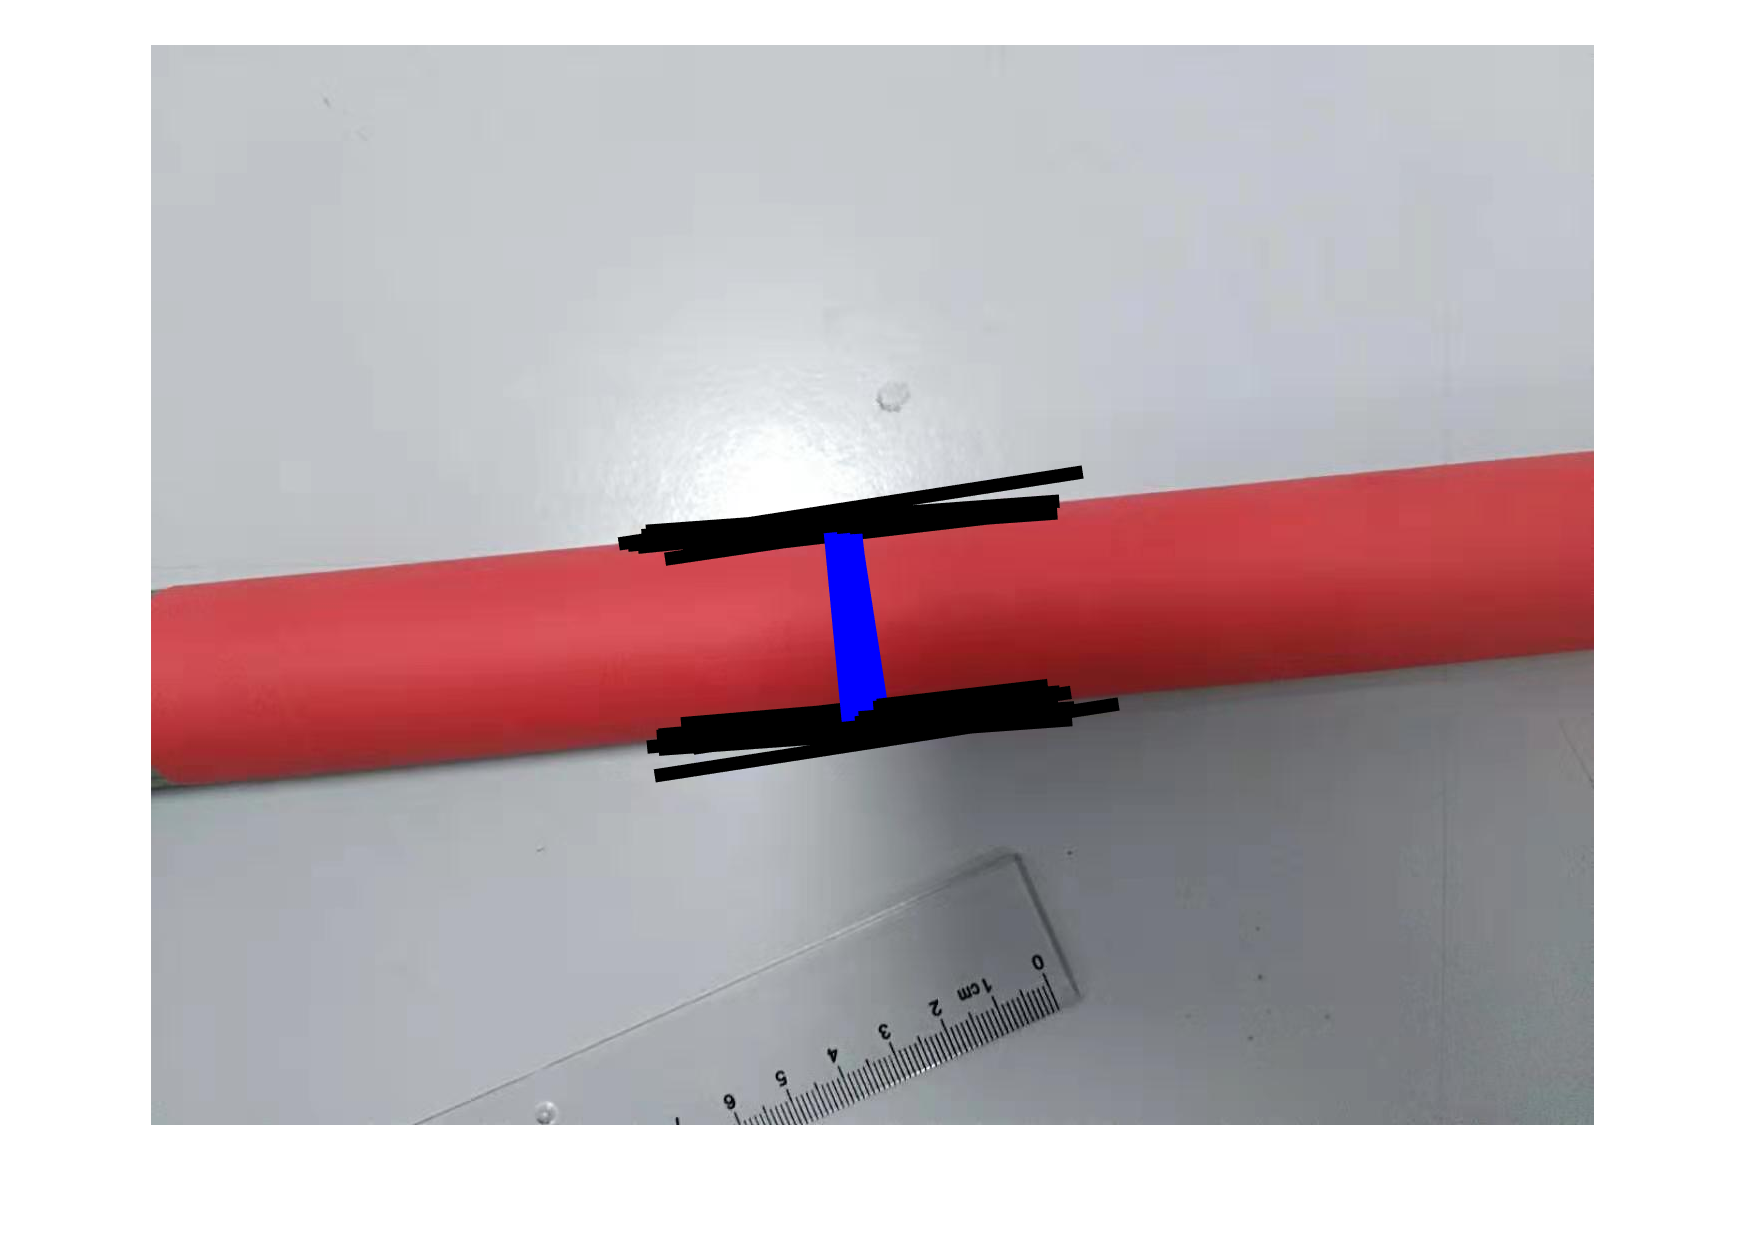

figure, imshow(img), hold on
plot_ruler(p1,p2);
for i=1:10
    [dp1, dp2] = compute_dp(p1,p2,ps,grad,pan_m,rot_m,spr_m,3,5,[50, 150],10);
    
    v1 = (v1+dp1)*(1-damping);
    v2 = (v2+dp2)*(1-damping);
    
    p1 = p1+v1;
    p2 = p2+v2;
    %figure, imshow(img), hold on
    plot_ruler(p1,p2);
end

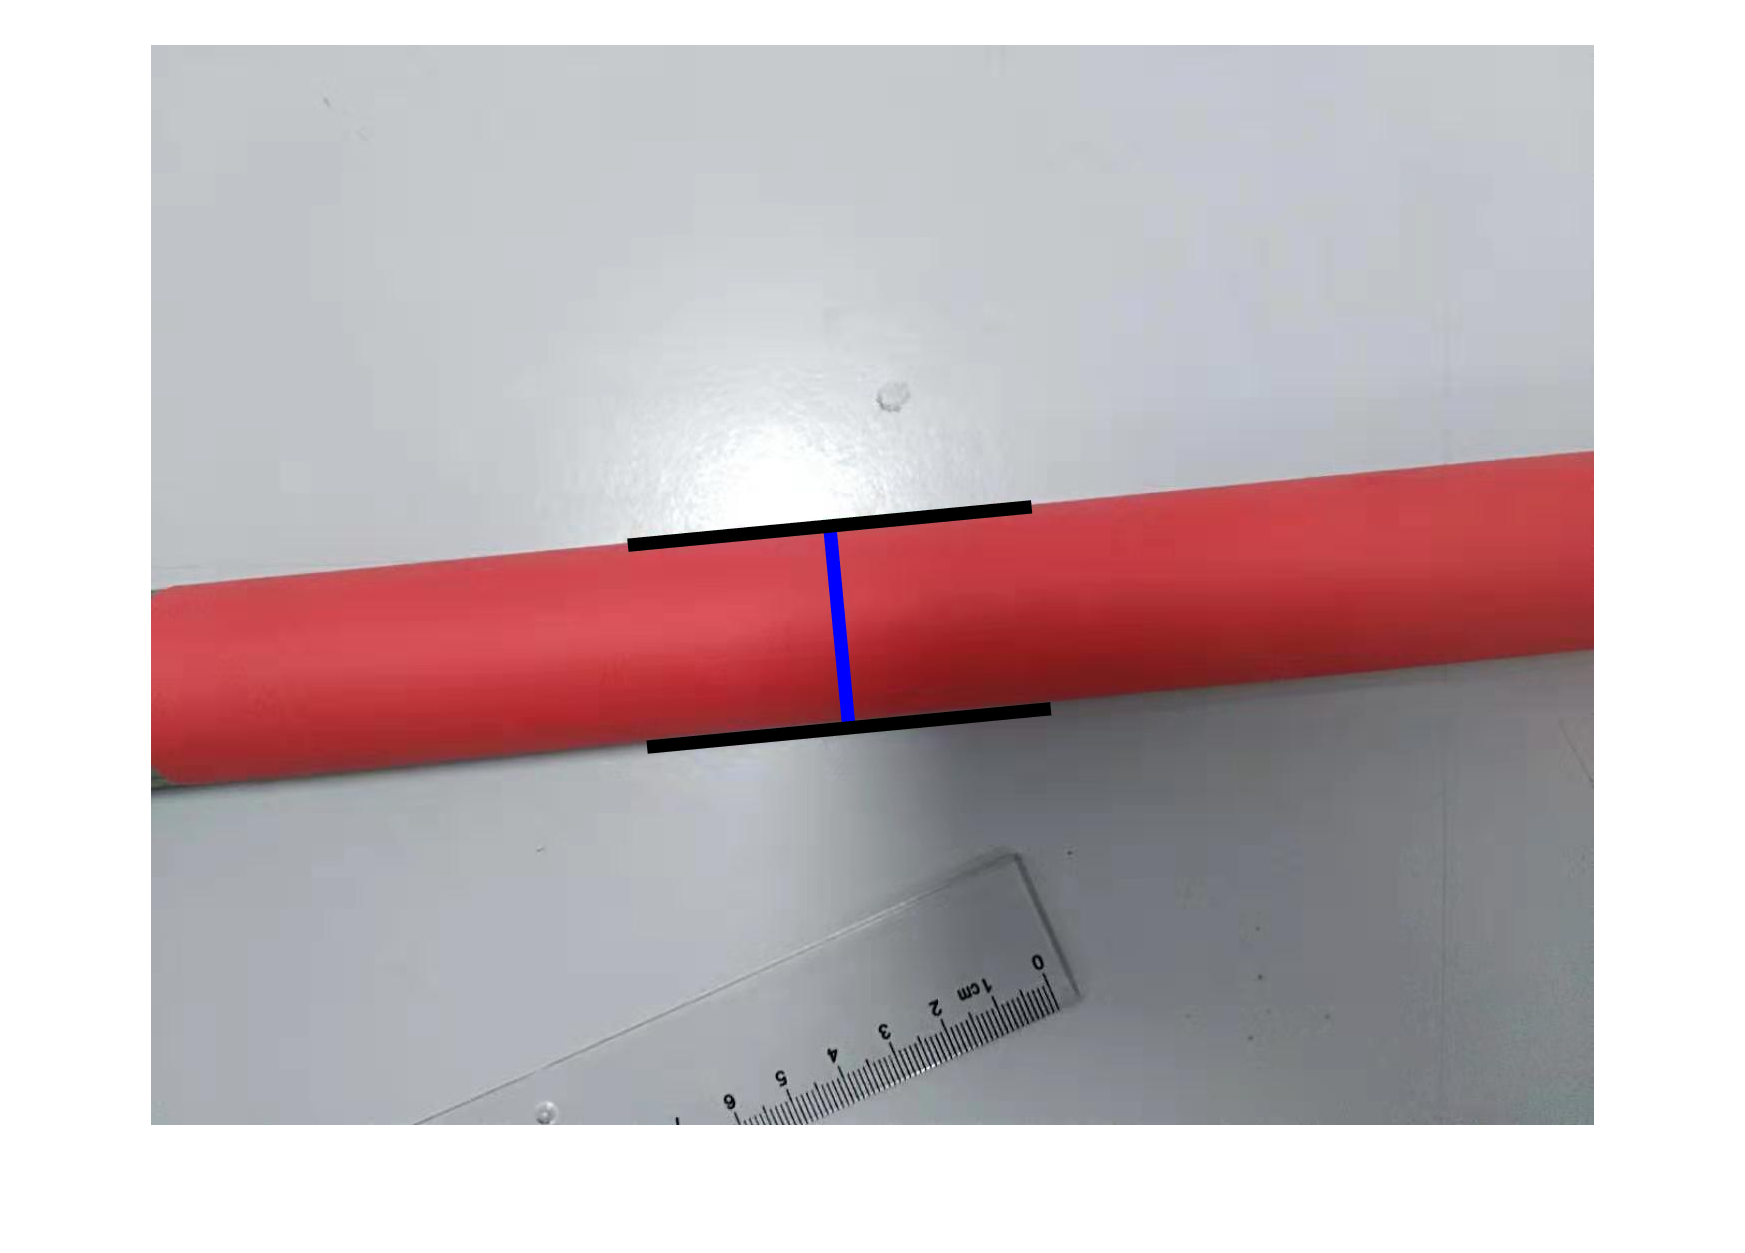

figure, imshow(img), hold on
plot_ruler(p1,p2);